## First test with the TDL channel 

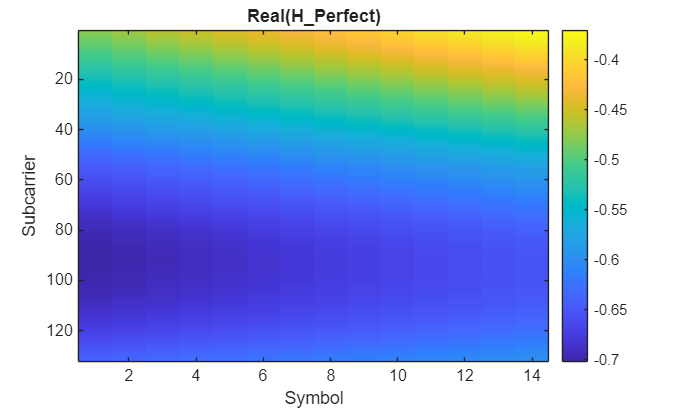

ue = nrCarrierConfig;
ue.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue.SubcarrierSpacing = 15;  % 15, 30, 60, 120, 240 (kHz)
ue.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel = nrTDLChannel;
channel.DelayProfile = 'TDL-C';
channel.DelaySpread = 40e-9;
channel.MaximumDopplerShift = 30;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
channel.Seed = 5;

% Set channel sample rate
ofdmInfo = nrOFDMInfo(ue);
channel.SampleRate = ofdmInfo.SampleRate;

% Get the maximum delay of the channel
chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;

% Reset random generator for reproducibility
rng('default');

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(ue,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(ue,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];

pathFilters = getPathFilters(channel);
[rxWaveform1,pathGains] = channel(txWaveform1);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid1 = nrOFDMDemodulate(ue,rxWaveform1(1+offset:end,:));
hEstPerfect = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);    

figure; imagesc(real(hEstPerfect)); colorbar; title('Real(H\_Perfect)') 
xlabel('Symbol'); ylabel('Subcarrier')

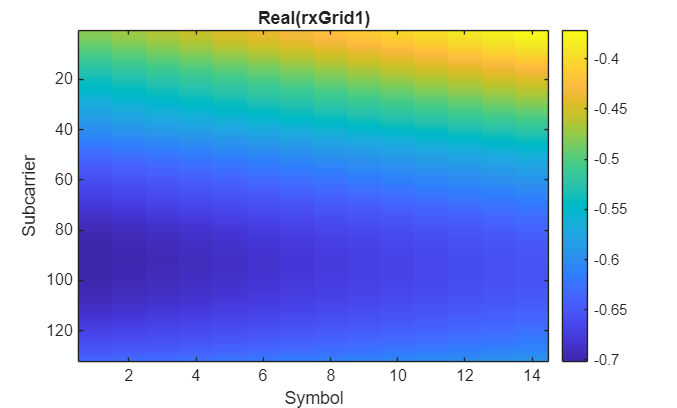

figure; imagesc(real(rxGrid1)); colorbar; title('Real(rxGrid1)')
xlabel('Symbol'); ylabel('Subcarrier')

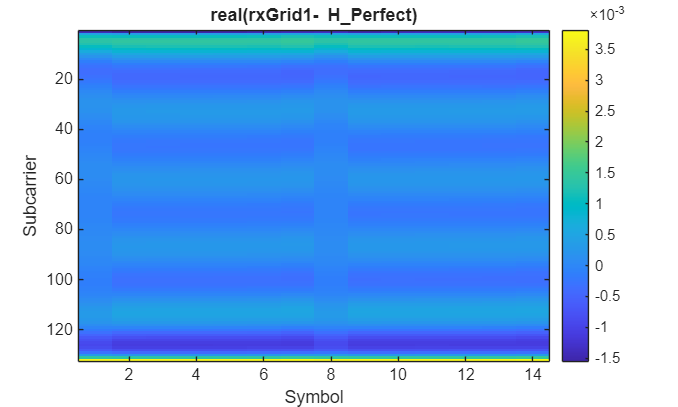

figure; imagesc(real(rxGrid1-hEstPerfect)); colorbar; title('real(rxGrid1- H\_Perfect)')
xlabel('Symbol'); ylabel('Subcarrier')

Elements at 2 edges of the bandwidth are quite off the range - if we cut off these elements, the range of the txGrid is mostly similar to the channel got from nrChannelEstimate

## Now test with NTN-TDL channel

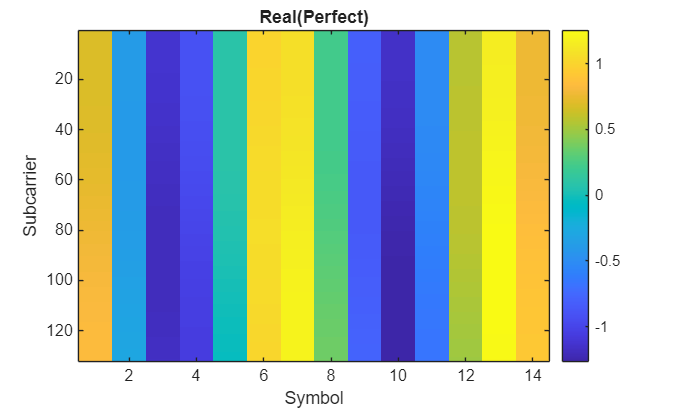

simParameters.CarrierFrequency = 2.18e9; %19e9; % 2.18e9;                  % Carrier frequency (in Hz)
simParameters.SatelliteAltitude = 600000;

simParameters.ElevationAngle = 50;                     % Elevation angle (in degrees)
simParameters.MobileSpeed = 5*1000/3600;               % Speed of mobile terminal (in m/s)
simParameters.MobileAltitude = 0;

ue = nrCarrierConfig;
ue.NSizeGrid = 11;          % Bandwidth in number of resource blocks (52RBs at 15kHz SCS for 10MHz BW)
ue.SubcarrierSpacing = 30;  % 15, 30, 60, 120, 240 (kHz)
ue.CyclicPrefix = 'Normal'; % 'Normal' or 'Extended'

waveformInfo = nrOFDMInfo(ue);
simParameters.SampleRate = waveformInfo.SampleRate;
c = physconst("lightspeed");
satelliteDopplerShift = dopplerShiftCircularOrbit( ...
    simParameters.ElevationAngle,simParameters.SatelliteAltitude, ...
    simParameters.MobileAltitude,simParameters.CarrierFrequency);

nTxAnts = 1;  % Number of transmit antennas
nRxAnts = 1;  % Number of receive antennas
nLayers = min(nTxAnts,nRxAnts);

channel = nrTDLChannel;
channel.DelayProfile = 'NTN-TDL-D';
channel.DelaySpread = 30e-9;
channel.SatelliteDopplerShift = satelliteDopplerShift;
channel.MaximumDopplerShift = simParameters.MobileSpeed*simParameters.CarrierFrequency/c;
% channel.MaximumDopplerShift = 0;
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;
% channel.Seed = 5;
% Set channel sample rate
ofdmInfo = nrOFDMInfo(ue);
channel.SampleRate = ofdmInfo.SampleRate;

% Get the maximum delay of the channel
% chInfo = info(channel);
% maxChDelay = chInfo.MaximumChannelDelay;
chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + ...
    chInfo.ChannelFilterDelay;

% Reset random generator for reproducibility
rng('default');

% Create a slot-wise resource grid empty grid
txGrid = nrResourceGrid(ue,nTxAnts);

txGrid1 = ones(size(txGrid));
[txWaveform1,~] = nrOFDMModulate(ue,txGrid1);
txWaveform1 = [txWaveform1; zeros(maxChDelay, size(txWaveform1,2))];

pathFilters = getPathFilters(channel);
[rxWaveform1,pathGains] = channel(txWaveform1);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid1 = nrOFDMDemodulate(ue,rxWaveform1(1+offset:end,:));
hEstPerfect = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);   

txGrid1 = ones(size(txGrid));

[rxWaveform1,pathGains] = channel(txWaveform1);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid1 = nrOFDMDemodulate(ue,rxWaveform1(1+offset:end,:));

figure; imagesc(real(hEstPerfect)); colorbar; title('Real(Perfect)') 
xlabel('Symbol'); ylabel('Subcarrier');

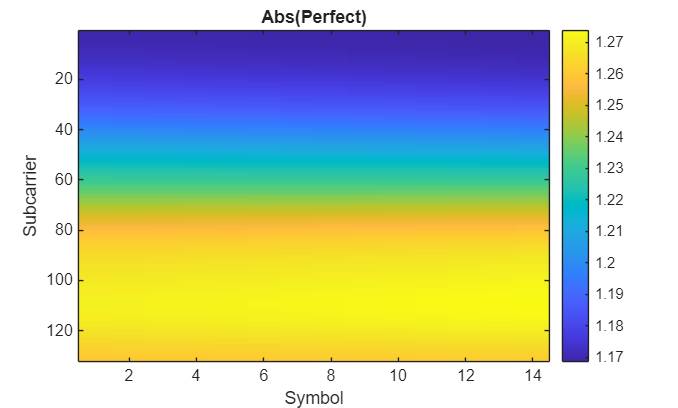

figure; imagesc(abs(hEstPerfect)); colorbar; title('Abs(Perfect)') 
xlabel('Symbol'); ylabel('Subcarrier');

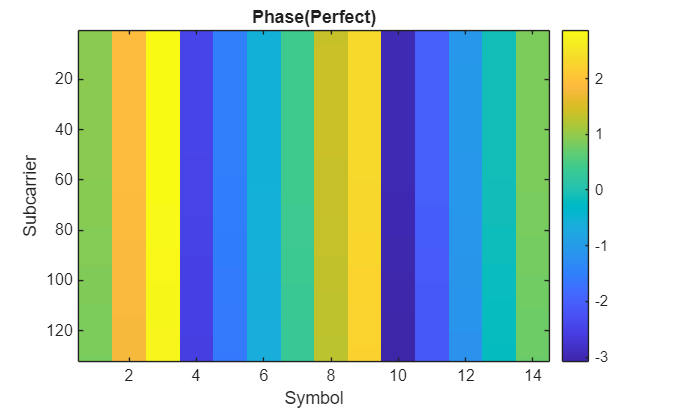

% [R G B]
% custom_map = [
%     71/255, 68/255,  232/255;  % Deep Blue   (-pi)
%     64/255, 202/255, 141/255;  % Green       (-pi/2)
%     246/255, 224/255, 40/255;  % Soft Yellow (0)
%     64/255, 202/255, 141/255;  % Green       (+pi/2)
%     71/255, 68/255,  232/255;  % Deep Blue   (+pi)
% ];
% % Interpolate to make it smooth (e.g., 256 levels)
% xq = linspace(1, size(custom_map,1), 256);
% my_cyclic_map = interp1(1:size(custom_map,1), custom_map, xq);

figure; imagesc(angle(hEstPerfect)); 
% colormap(my_cyclic_map); 
colorbar; title('Phase(Perfect)') 
xlabel('Symbol'); ylabel('Subcarrier');

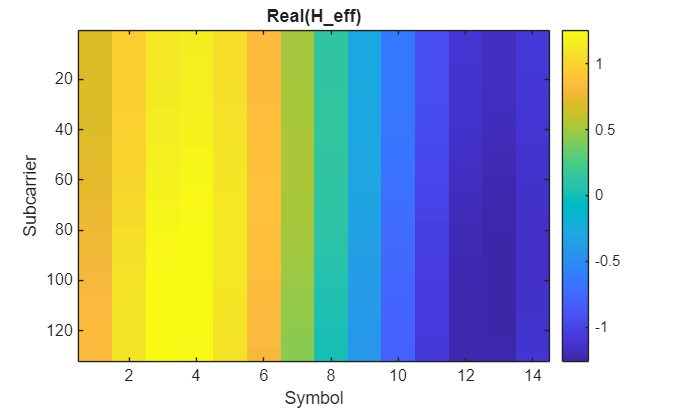


% H_eff when we compensate symbol-wise
for n = 1:14
    % if n==1
    %     t_n = ofdmInfo.CyclicPrefixLengths(n);
    % else
    %     t_n = ofdmInfo.CyclicPrefixLengths(n) + ofdmInfo.SymbolLengths(n-1);
    % end
    t_n= (n-1)*256;
    % t_n = t_n / simParameters.SampleRate; 
    H_perfect_n(:, n) = hEstPerfect(:, n) * exp(1i*2*pi*satelliteDopplerShift*t_n);
end
figure; imagesc(real(H_perfect_n)); colorbar; title('Real(H\_eff)')
xlabel('Symbol'); ylabel('Subcarrier');

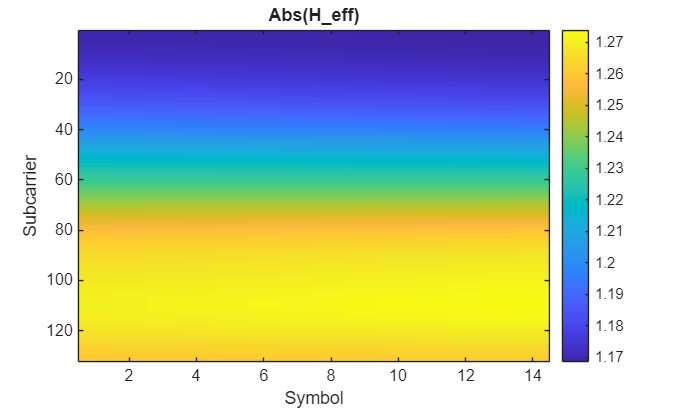

figure; imagesc(abs(H_perfect_n)); colorbar; title('Abs(H\_eff)')
xlabel('Symbol'); ylabel('Subcarrier');

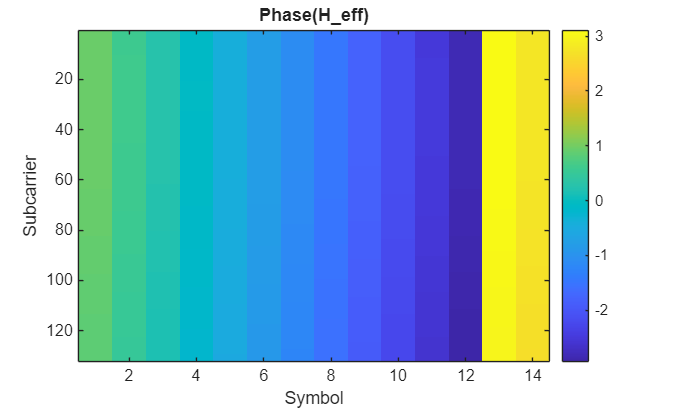

figure; imagesc(angle(H_perfect_n)); colorbar; title('Phase(H\_eff)')
% colormap hsv;
xlabel('Symbol'); ylabel('Subcarrier');

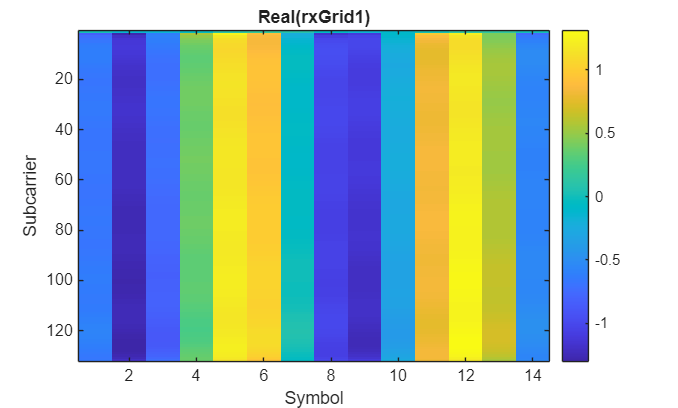

% check to see if rxGrid1 equal to hEstPerfect channel grid
figure; imagesc(real(rxGrid1)); colorbar; title('Real(rxGrid1)')
xlabel('Symbol'); ylabel('Subcarrier');

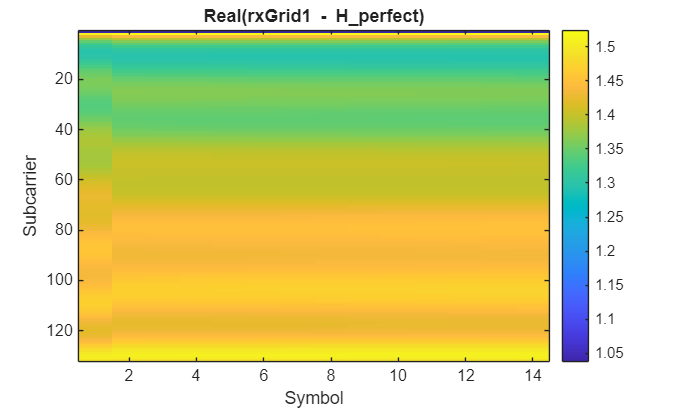

figure; imagesc(abs(rxGrid1-hEstPerfect)); colorbar; title('Real(rxGrid1 - H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

the top subcarrier elements are not similar to the perfect channel 

### Check the effective channel when we compensate sample-wise

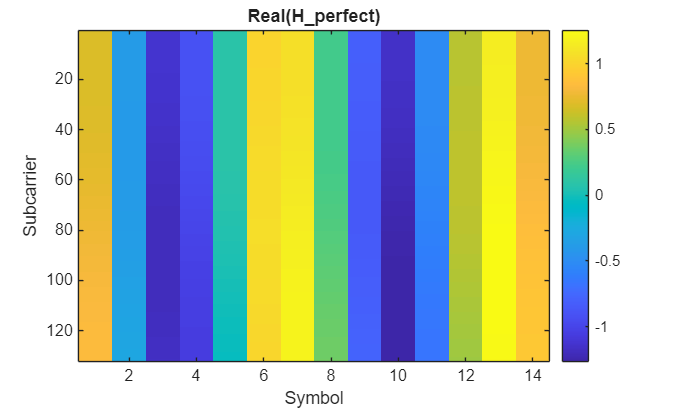

reset(channel);
% sample-wise Doppler precompensate
t = (0:size(txWaveform1,1)-1)'/simParameters.SampleRate;
txWaveform2 = txWaveform1.*exp(1j*2*pi*(-satelliteDopplerShift)*t);

[rxWaveform2,pathGains] = channel(txWaveform2);
pathFilters = getPathFilters(channel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);
rxGrid2 = nrOFDMDemodulate(ue,rxWaveform2(1+offset:end,:));
hEstPerfect2 = nrPerfectChannelEstimate(ue,pathGains,pathFilters,offset);    

figure; imagesc(real(hEstPerfect2)); colorbar; title('Real(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

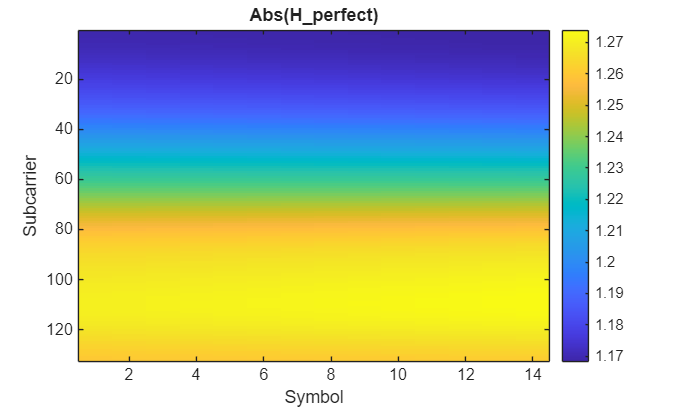

figure; imagesc(abs(hEstPerfect2)); colorbar; title('Abs(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

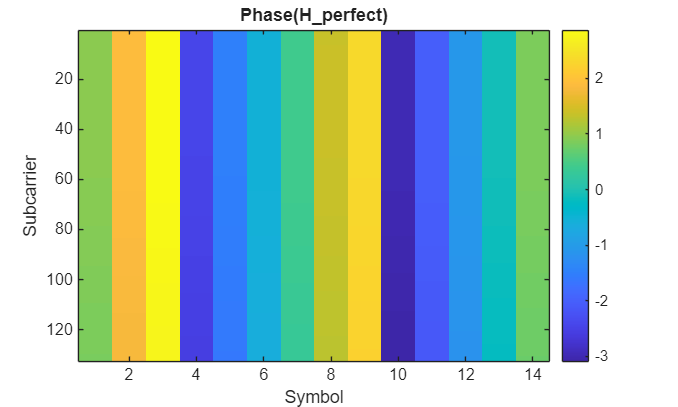

figure; imagesc(angle(hEstPerfect2)); colorbar; title('Phase(H\_perfect)')
xlabel('Symbol'); ylabel('Subcarrier');

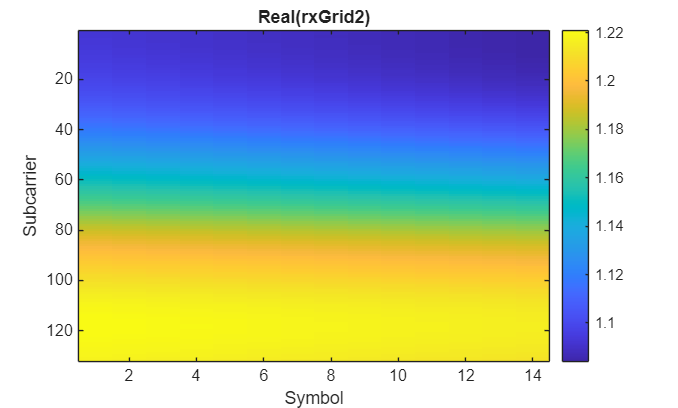

figure; imagesc(real(rxGrid2)); colorbar; title('Real(rxGrid2)')
xlabel('Symbol'); ylabel('Subcarrier');

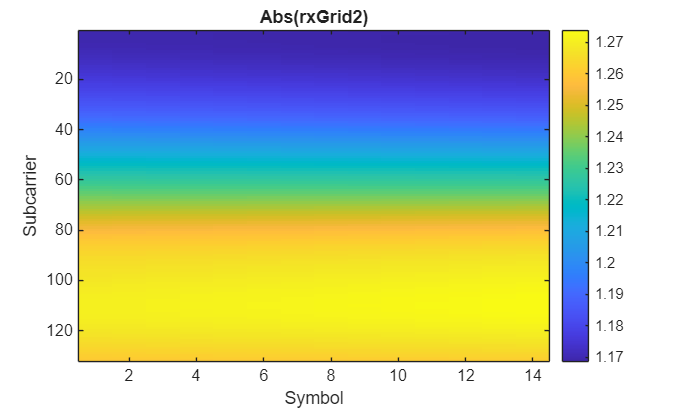

figure; imagesc(abs(rxGrid2)); colorbar; title('Abs(rxGrid2)')
xlabel('Symbol'); ylabel('Subcarrier');

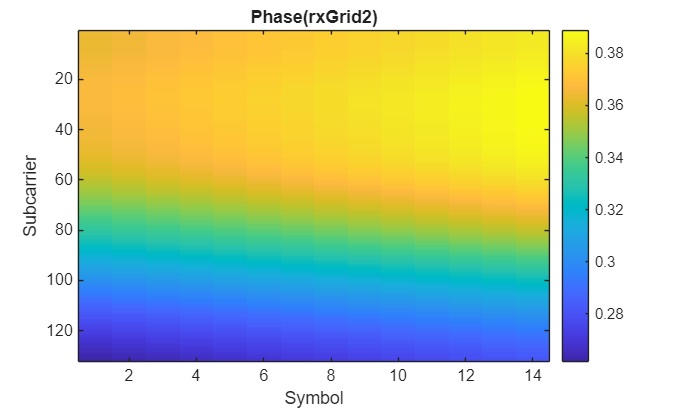


figure; imagesc(angle(rxGrid2)); colorbar; title('Phase(rxGrid2)')
xlabel('Symbol'); ylabel('Subcarrier');